clc;clear;
% % % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% % data = fread(fid,'short');
% data = read_complex_binary('/mnt/tmp/usrp_20_multi.dat'); 
% load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/heltf20_total.mat")
% load('/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/HELTF20_tx_bb.mat');

% 
% 
% i = 1;
% symbollen_table = [288, 576, 1152];
% gilen_table = [32, 64, 128];
% symbollen = symbollen_table(i);
% gilen = gilen_table(i);
% 

% % time domain
% N0 = 978;
% figure
% plot(real(data))
% hold on
% plot(imag(data))
% % plot(imag(data(N0+1:N0+288)))
% % hold on 
% % plot(real(bb(1,:))./ 1.5)
% % hold on 
% 
% 
% figure
% corr_result = conv(data, bb(1,:));
% plot(abs(corr_result))
% hold on
% 
% figure()
% Fs = 200e6;
% t = 0:1/Fs:0.000001-1/Fs % 1000 points
% N = length(t);
% y0 = abs(fft(data(N0+1:N0+N)));
% f = (0:N-1)*Fs/N;
% plot(f,y0);
% % plot(abs(fftshift((fft(data(1:10000))))))
% hold on 
% 
% figure()
% f1 = (0:N-1)*Fs/N-Fs/2;
% y1 = abs(fftshift(fft(data(N0+1:N0+N))));
% plot(f1,y1);
% hold on
% 
% figure
% cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
% plot(abs(cfr_bb))
% hold on
% 
% % decode part 
% % freq shift
% % fc = 5825e6;
% % baseband_data = data.* exp(2*pi*1i*f_center*t);
% % loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% % data = data.*loc_carr;
% 
% pos = N0;
% cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
% plot(abs(cfr_recv))
% hold on
% % plot(real(cfr_recv))
% % hold on
% 
% cir1 = zeros(cfg.users, cfg.fftlen);
% 
% figure
% for u=1:cfg.users
% cir1(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% plot(abs(cir1(1,:)))
% hold on
% end


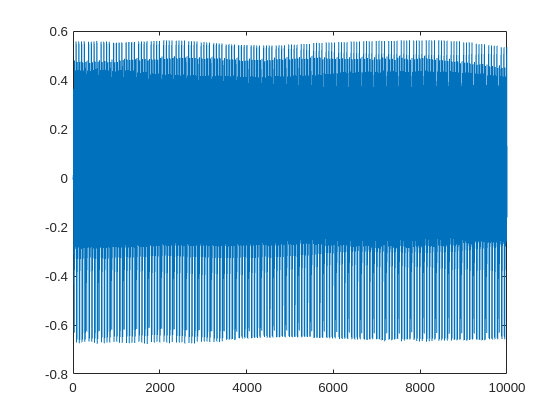


% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20_rx2.dat');
data = read_complex_binary('/mnt/tmp/usrp_20_multi.dat'); 
load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/heltf20.mat")
load('/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/HELTF20_tx_bb.mat');
i = 1;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


data1 = [data(278-32:end); zeros(symbollen - mod(length(data(278-32:end)), symbollen), 1)];
data1 = reshape(data1, [symbollen, length(data1) / symbollen]);

figure
plot(imag(data(1:10000)))
hold on

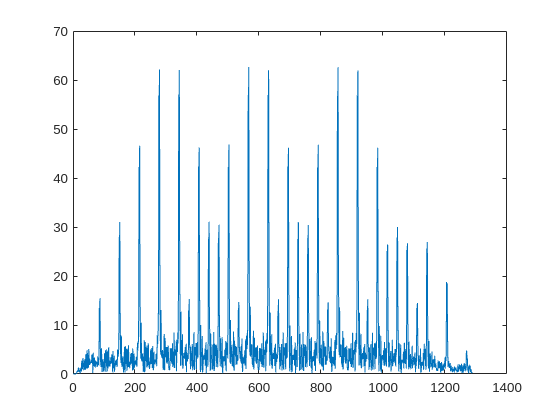

% plot(real(data(1:10000)))
% hold on

cfr_all=fftshift(fft(data1(cfg.gilen+1:end,:)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
corr_result = conv(data(1:1000), bb(1,1:end));
figure
plot(abs(corr_result))
hold on

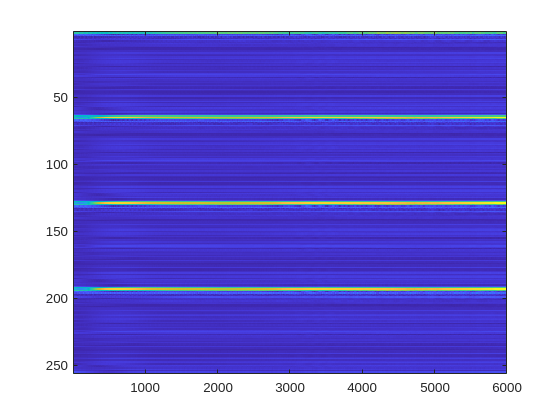

figure
imagesc(abs(cir(:,1:6000)))
hold on% xlim([1 500])

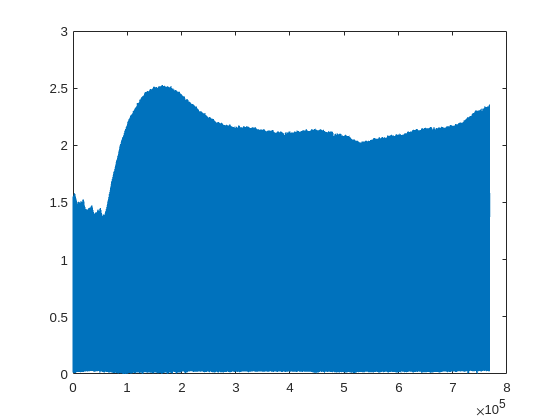

figure
plot(abs(cir(1:256*3000)))
hold on

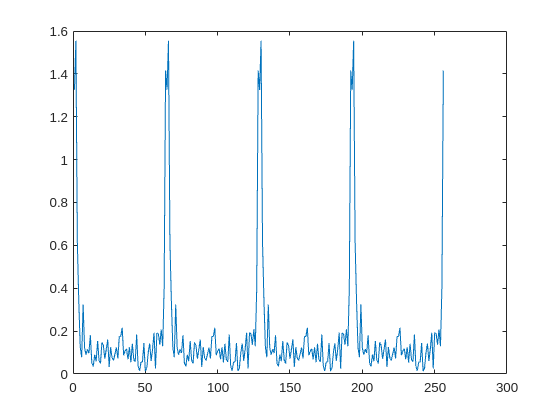

figure
plot(abs(cir(1:256)))
hold on

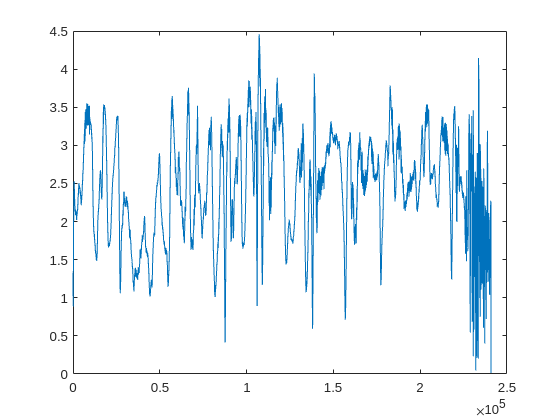


figure
plot(abs(cir(65,:)))
hold on

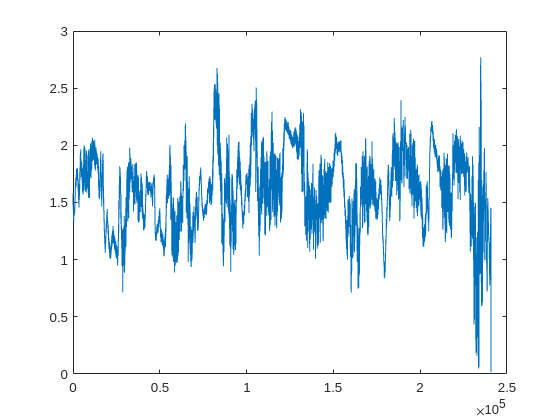


figure
plot(abs(cir(66,:)))
hold on

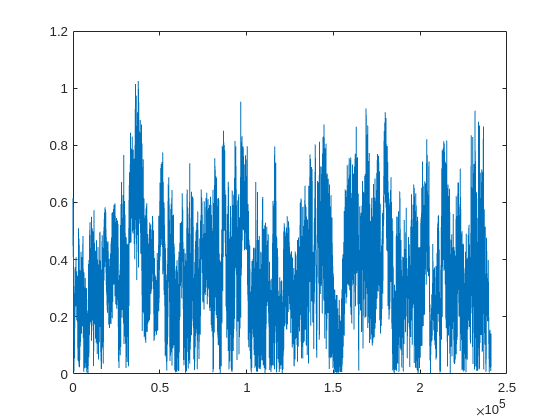


figure
plot(abs(cir(67,:)))
hold on

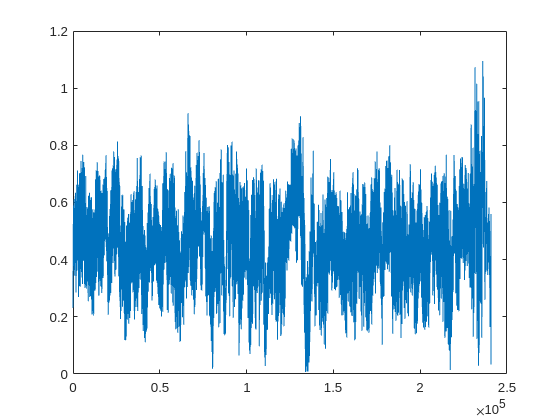


figure
plot(abs(cir(68,:)))
hold on

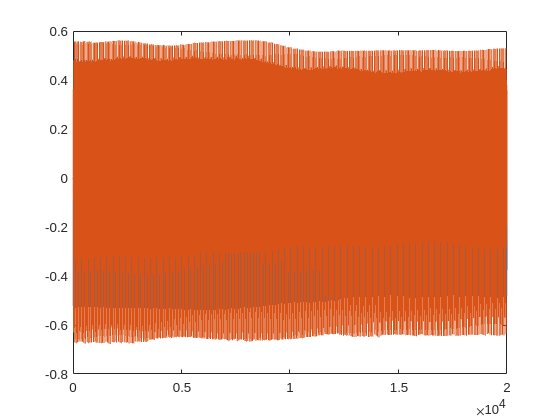

% time domain
N0 = 489;
figure
plot(real(data(1:20000)))
hold on
plot(imag(data(1:20000)))

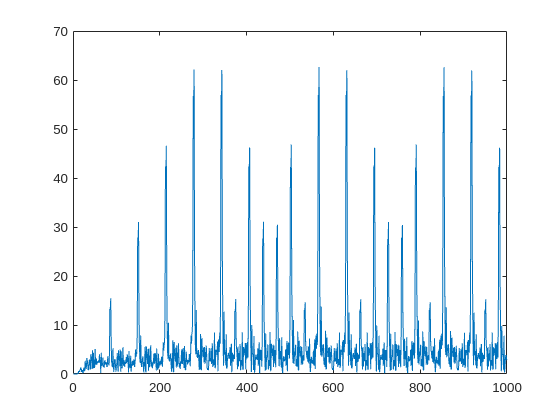

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data(1:10000), bb(1,:));
plot(abs(corr_result(1:1000)))
hold on


% figure()
% Fs = 200e6;
% t = 0:1/Fs:0.000001-1/Fs % 1000 points
% N = length(t);
% y0 = abs(fft(data(N0+1:N0+N)));
% f = (0:N-1)*Fs/N;
% plot(f,y0);
% % plot(abs(fftshift((fft(data(1:10000))))))
% hold on 
% 
% figure()
% f1 = (0:N-1)*Fs/N-Fs/2;
% y1 = abs(fftshift(fft(data(N0+1:N0+N))));
% plot(f1,y1);
% % hold on
% 
% figure
% cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
% plot(abs(cfr_bb))
% hold on

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;
row = 0;
num = 8000

num = 8000

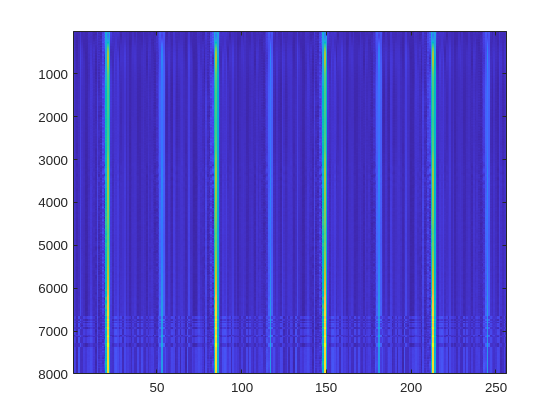

cir2 = zeros(num+1, cfg.fftlen);

for N = N0:symbollen:N0+num*symbollen
pos = N;
row = row+1;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';

% plot(abs(cfr_recv))
% hold on
% plot(real(cfr_recv))
% hold on

t3 = 1:12.5:12.5*1024;
cir2(row,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))))';

end
% plot(abs(cir1(1,:)))
% hold on
% end
% 
% figure
% plot(abs(cir1(1,:)))
% hold on
figure
imagesc(abs(cir2))
hold on% xlim([1 500])

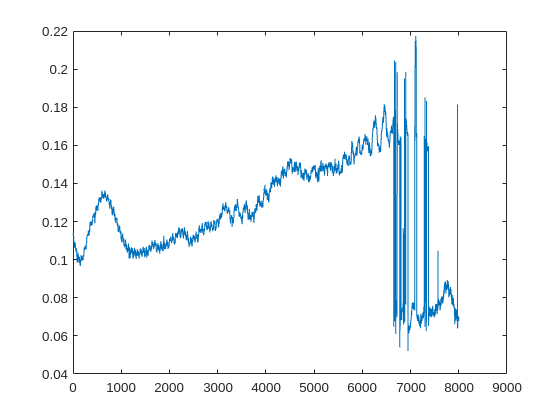


figure
plot(abs(cir2(:,30)))
hold on

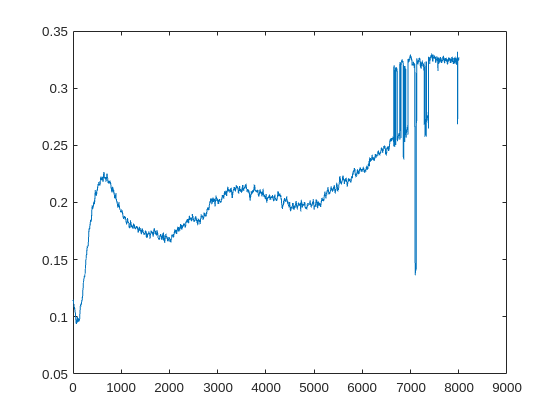


figure
plot(abs(cir2(:,31)))
hold on

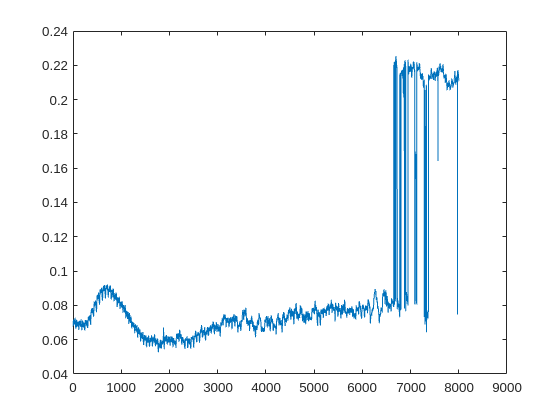


figure
plot(abs(cir2(:,32)))
hold on

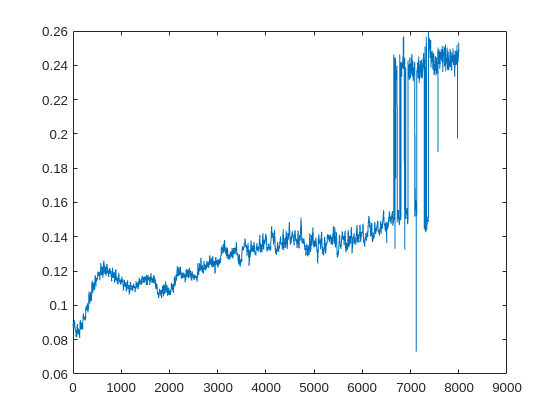


figure
plot(abs(cir2(:,33)))
hold on

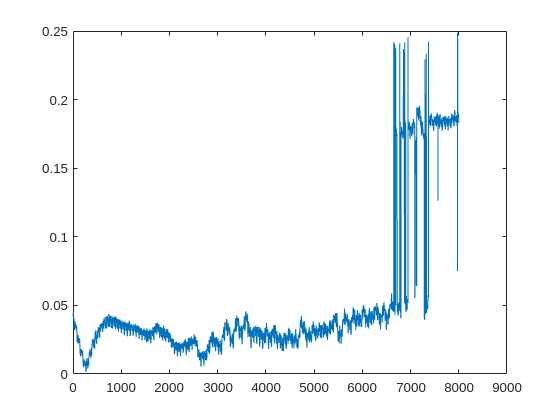


figure
plot(abs(cir2(:,34)))
hold on

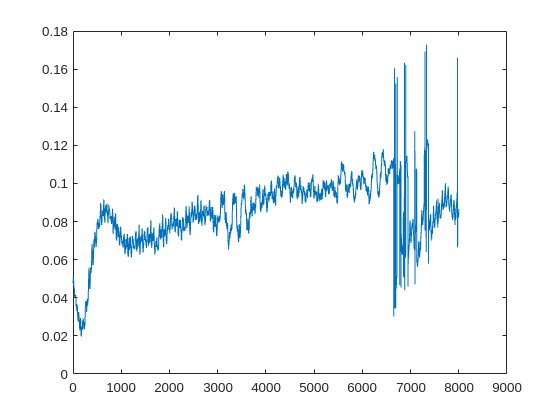


figure
plot(abs(cir2(:,35)))
hold on

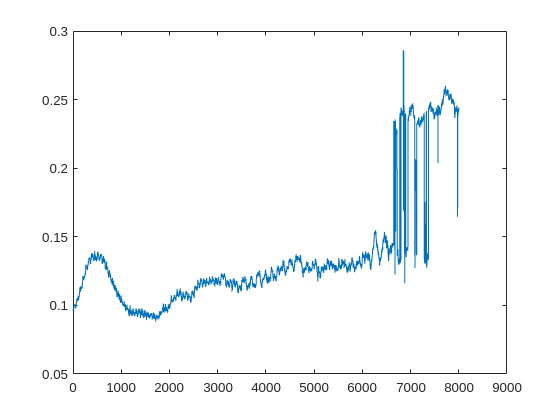


figure
plot(abs(cir2(:,36)))
hold on

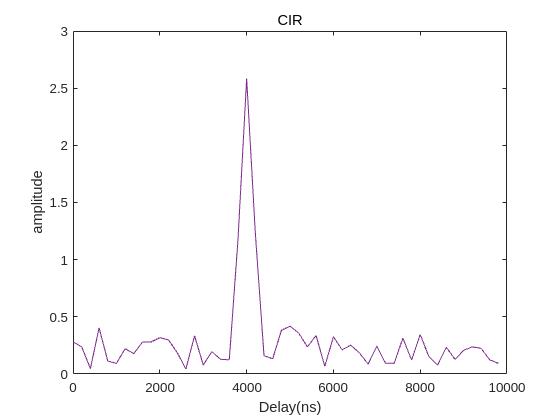


figure
for u=1:cfg.users
cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(1:200:200*50,abs(cir2(1,1:50)))
% plot(1:50:50*1024, abs(cir2(1,:)))
hold on

end
xlabel('Delay(ns)')
ylabel('amplitude')
title('CIR')